# Autoencoders for Wireless Communications

This example shows how to model an end-to-end communications system with an autoencoder to reliably transmit information bits over a wireless channel.

## Introduction

A traditional autoencoder is an unsupervised neural network that learns how to efficiently compress data, which is also called encoding. The autoencoder also learns how to reconstruct the data from the compressed representation such that the difference between the original data and the reconstructed data is minimal. 

Traditional wireless communication systems are designed to provide reliable data transfer over a channel that impairs the transmitted signals. These systems have multiple components such as channel coding, modulation, equalization, synchronization, etc. Each component is optimized independently based on mathematical models that are simplified to arrive at closed form expressions. On the contrary, an autoencoder jointly optimizes the transmitter and the receiver as a whole. This joint optimization has the potential of providing a better performance than the traditional systems [1],[2]. 

Traditional autoencoders are usually used to compress images, in other words remove redundancies in an image and reduce its dimension. A wireless communication system on the other hand uses channel coding and modulation techniques to add redundancy to the information bits. With this added redundancy, the system can recover the information bits that are impaired by the wireless channel. So, a wireless autoencoder actually adds redundancy and tries to minimize the number of errors in the received information for a given channel while learning to apply both channel coding and modulation in an unsupervised way. 

## Basic Autoencoder System

The following is the block diagram of a wireless autoencoder system. The encoder (transmitter) first maps $k$ information bits into a message s such that $s \in \{1,\dots,M\}$, where $M=2^k$. Then message s is mapped to n real number to create $\textbf{x} =f(s) \in \mathbb{R}^{n}$. The last layer of the encoder imposes constraints on $\textbf{x}$ to further restrict the encoded symbols. The following are possible such constraints and are implemented using the normalization layer:

- Energy constraint: $\Vert x \Vert^2_2\le n$

- Average power constraint: $\mathbb{E} \lbrack |x_i|^2 \rbrack \le 1, \forall i$

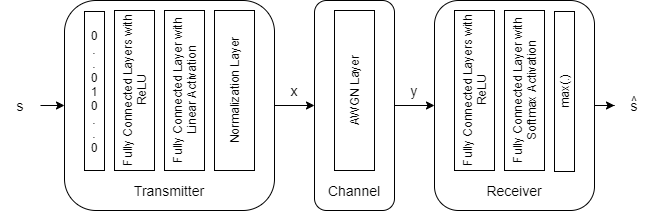

Define the communication rate of this system as $R=k/n$ [bits/channel use], where (*n*,*k*) means that the system sends one of $M=2^k$ messages using *n* channel uses. The channel impairs encoded (i.e. transmitted) symbols to generate $\textbf{y} \in \mathbb{R}^{n}$. The decoder (i.e. receiver) produces an estimate, $\hat{s}$, of the transmitted message, $s$. 

The input message is defined as a one-hot vector $\textbf{1}_s \in \mathbb{R}^M$, which is defined as a vector whose elements are all zeros except the $s^{\textrm{th}}$ one. The channel is additive white Gaussian noise (AWGN) that adds noise to achieve a given energy per data bit to noise power density ratio, $E_b/N_o$. 

The autoencoder maps $k$ data bits into $n$ channel uses, which results in an effective coding rate of $R=k/n$ data bits per channel use. Then, 2 channel uses are mapped into a symbol, which results in 2 channel uses per symbol. Map the channel uses per channel symbol value to the `BitsPerSymbol` parameter of the AWGN channel. 

Define a (7,4) autoencoder network with energy normalization and a training $E_b/N_o$ of 3 dB. In [1], authors showed that two fully connected layers for both the encoder (transmitter) and the decoder (receiver) provides the best results with minimal complexity. Input layer ([featureInputLayer](docid:nnet_ref#object_layer.featureinputlayer)) accepts a one-hot vector of length M. The encoder has two fully connected layers ([fullyConnectedLayer](docid:nnet_ref#mw_1e7fbc56-4746-4f30-8cd9-7048ce806a0d)). The first one has M inputs and M outputs and is followed by an ReLU layer ([reluLayer](docid:nnet_ref#mw_ca5427bd-5cdc-4a58-ba63-302c257d8222)). The second fully connected layer has M inputs and n outputs and is followed by the normalization layer ([helperAEWNormalizationLayer.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWNormalizationLayer.m'))). The encoder layers are followed by the AWGN channel layer ([helperAEWAWGNLayer.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWAWGNLayer.m'))). The output of the channel is passed to the decoder layers. The first decoder layer is a fully connected layer that has n inputs and M outputs and is followed by an ReLU layer. The second fully connected layer has M inputs and M outputs and is followed by a softmax layer ([softmaxLayer](docid:nnet_ref#mw_a09d3c68-d062-4692-a950-9a7fea5c40c3)), which outputs the probability of each M symbols. The classification layer ([classificationLayer](docid:nnet_ref#bu5lho8)) outputs the most probable transmitted symbol from 0 to M-1. 

% 입력 비트 수 및 관련 파라미터 설정
k = 3;    % 입력 비트 수 (number of input bits)
M = 2^k;  % 가능한 입력 심볼의 수 (number of possible input symbols)
n = 7;    % 채널 사용 수 (number of channel uses)
EbNo = 3; % 에너지 대 잡음 비율(Eb/No) (in dB)

% 코드율을 사용하여 채널 Eb/No 값으로 변환
R = k/n;  
EbNoChannel = EbNo + 10*log10(R);

% 오토인코더 네트워크 구성
wirelessAutoencoder = [
  featureInputLayer(M, "Name", "One-hot input", "Normalization", "none")  % One-hot 인코딩된 입력을 받는 입력층
  
  fullyConnectedLayer(M, "Name", "fc_1")  % 첫 번째 완전 연결층
  reluLayer("Name", "relu_1")  % ReLU 활성화 함수
  
  fullyConnectedLayer(n, "Name", "fc_2")  % 두 번째 완전 연결층
  
  helperAEWNormalizationLayer("Method", "Energy", "Name", "wnorm")  % 에너지 정규화를 위한 레이어
  
  % Rayleigh 페이딩 레이어를 추가합니다.
  helperAEWAWGNLayer("Name", "rayleigh_fading", ...  % Rayleigh 페이딩 레이어
    "NoiseMethod", "EsNo", ...  % NoiseMethod는 'EsNo'로 설정
    "EsNo", EbNoChannel, ...  % Es/No 값
    "BitsPerSymbol", k, ...  % 비트당 심볼 수
    "SignalPower", 1) % 신호 전력
    
  fullyConnectedLayer(M, "Name", "fc_3")  % 세 번째 완전 연결층
  reluLayer("Name", "relu_2")  % ReLU 활성화 함수
  
  fullyConnectedLayer(M, "Name", "fc_4")  % 네 번째 완전 연결층
  softmaxLayer("Name", "softmax")  % 소프트맥스 출력층
  
  classificationLayer("Name", "classoutput")  % 클래스 분류 레이어 (출력 심볼 결정)
];



The [`helperAEWTrainWirelessAutoencoder.m`](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWTrainWirelessAutoencoder.m')) function defines such a network based on the (n,k), normalization method and the $E_b/N_o$ values.

### Train Autoencoder

Run the [`helperAEWTrainWirelessAutoencoder.m`](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWTrainWirelessAutoencoder.m')) function to train a (2,2) autoencoder with energy normalization. This function uses the [trainingOptions](docid:nnet_ref#bu59f0q) function to select 

- Adam (adaptive moment estimation) optimizer, 

- Initial learning rate of 0.08, 

- Maximum epochs of 10,

- Minibatch size of 100*M,

- Piecewise learning schedule with drop period of 5 and drop factor of 0.1.

Then, the [`helperAEWTrainWirelessAutoencoder.m`](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWTrainWirelessAutoencoder.m')) function runs the [trainNetwork](docid:nnet_ref#bu6sn4c) function to train the autoencoder network with the selected options. Finally, this function separates the network into encoder and decoder parts. Encoder starts with the input layer and ends after the normalization layer. Decoder starts after the channel layer and ends with the classification layer. A feature input layer is added at the beginning of the decoder. 

Train the autoencoder with an $E_b/N_o$ value that is low enough to result in some errors but not too low such that the training algorithm cannot extract any useful information from the received symbols, y. Set $E_b/N_o$ to 3 dB. 

% 오토인코더 훈련을 위한 설정
n = 2;                      % 채널 사용 수 (number of channel uses)
k = 3;                      % 입력 비트 수 (number of input bits)
EbNo = 3;                   % 에너지 대 잡음 비율(Eb/No) (in dB)
normalization = "Energy";   % 정규화 방법 설정 ("Energy" | "Average power")

% 오토인코더 훈련 함수 호출
[txNet(1),rxNet(1),infoTemp,wirelessAutoEncoder(1)] = ...
  helperAEWTrainWirelessAutoencoder(n,k,normalization,EbNo);

Output z:
    1.1480
    0.1979

Output z:
    1.0267
    0.8829

Output z:
    0.9850
    1.0805

Output z:
   -1.0159   -0.2171    0.8248    0.4276   -0.2095   -0.3656    0.7195   -1.1129    0.7596    0.9235   -1.2128   -0.6800   -0.6173   -0.7596    0.6026   -0.3489    0.9986   -1.0005    0.5351    0.4335   -1.3792   -0.0536    0.9467    0.9890    0.6554    0.0565    1.0368   -0.6151   -1.0458    0.6922    0.0336    0.8017   -0.5539   -0.5076   -0.4539    0.4871    0.6010    0.6879    0.1332   -0.2108   -0.6973    0.8448   -0.3355    0.6984   -1.2552   -1.1959    0.1979   -0.1092   -0.4757    0.6782   -0.2075   -0.8551    0.6400   -1.0793   -0.4479    0.9417    0.5906   -1.3932    0.9899   -0.6555   -0.6013    0.8961   -1.5271   -0.2221    0.2417    0.5741    0.6289    0.9971    1.0756    0.6764   -0.4078    0.3288    0.1945   -1.0840   -0.7372   -0.0436    0.1414   -0.5798   -0.4994   -0.8362   -0.8957    0.6117   -0.4571   -0.2838   -0.9629    0.8871   -0.0612    0.2496   -0.2008 


% 훈련된 오토인코더의 정보를 저장
infoTemp.n = n;
infoTemp.k = k;
infoTemp.EbNo = EbNo;
infoTemp.Normalization = normalization;
info = infoTemp;


Plot the training progress. The validation accuracy quickly reaches more than 90% while the validation loss keeps slowly decreasing. This behavior shows that the training $E_b/N_o$ value was low enough to cause some errors but not too low to avoid convergence. For definitions of validation accuracy and validation loss, see [Monitor Deep Learning Training Progress](docid:nnet_ug#mw_507458b6-14c3-4a31-884c-9f2119ff7e05) section.

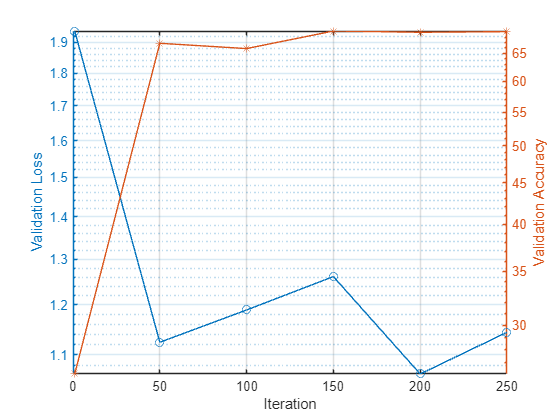

% 훈련 성능 그래프 출력
figure
helperAEWPlotTrainingPerformance(info(1))

Use the plot object function of the trained network objects to show the layer graphs of the full autoencoder, the encoder network, i.e. the transmitter, and the decoder network, i.e. the receiver.  

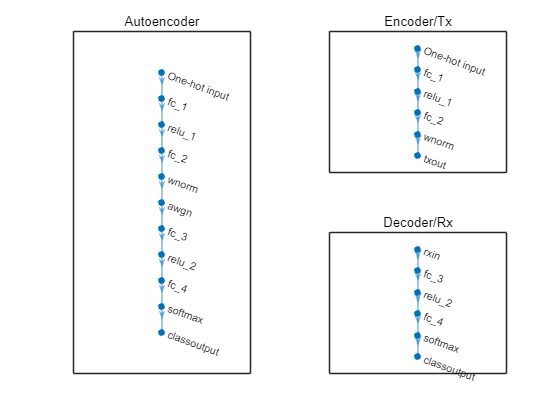

% 훈련된 오토인코더, 인코더(송신기), 디코더(수신기)의 레이어 구조를 시각화
figure
tiledlayout(2,2)
nexttile([2 1])
plot(wirelessAutoEncoder(1))  % 전체 오토인코더 구조
title('Autoencoder')
nexttile
plot(txNet(1))  % 인코더(송신기) 구조
title('Encoder/Tx')
nexttile
plot(rxNet(1))  % 디코더(수신기) 구조
title('Decoder/Rx')

## Simulate BLER Performance

Simulate the block error rate (BLER) performance of the (2,2) autoencoder. Set up simulation parameters.

% BLER 성능 시뮬레이션을 위한 설정
simParams.EbNoVec = 0:0.5:8;  % 시뮬레이션할 Eb/No 값들
simParams.MinNumErrors = 10;  % 최소 블록 오류 수 (minimum number of errors)
simParams.MaxNumFrames = 300; % 최대 프레임 수 (maximum number of frames)
simParams.NumSymbolsPerFrame = 10000; % 프레임당 심볼 수 (number of symbols per frame)
simParams.SignalPower = 1;    % 신호 전력 (signal power)

Generate random integers in the [0 $M$-1] range that represents $k$ random information bits. Encode these information bits into complex symbols with [`helperAEWEncode`](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWEncode.m')) function. `The helperAEWEncode` function runs the encoder part of the autoencoder then maps the real valued $\textbf{x}$ vector into a complex valued $\bf{x_c}$ vector such that the odd and even elements are mapped into the in-phase and the quadrature component of a complex symbol, respectively, where $\textbf{x}_c = \textbf{x}(1:2:end)+j\textbf{x}(2:2:end)$. In other words, treat the $\textbf{x}$ array as an interleaved complex array. 

Pass the complex symbols through an AWGN channel. Decode the channel impaired complex symbols with the [`helperAEWDecode`](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWDecode.m')) function. The following code runs the simulation for each $E_b/N_o$ point for at least 10 block errors. To obtain more accurate results, increase minimum number of errors to at least 100. If [Parallel Computing Toolbox™](https://www.mathworks.com/products/parallel-computing.html) is installed and a license is available, uncomment the `parfor` line to run the simulations on a parallel pool. 

Plot the constellation learned by the autoencoder to send symbols through the AWGN channel together with the received constellation. For a (2,2) configuration, autoencoder learns a QPSK ($M=2^k=4$) constellation with a phase rotation. 

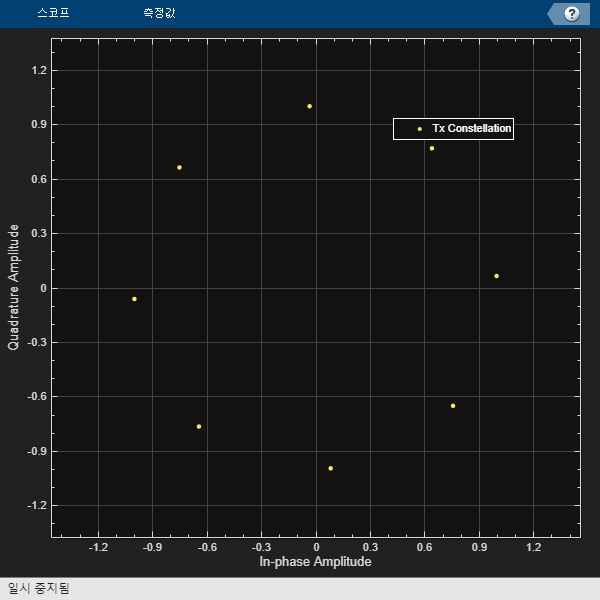

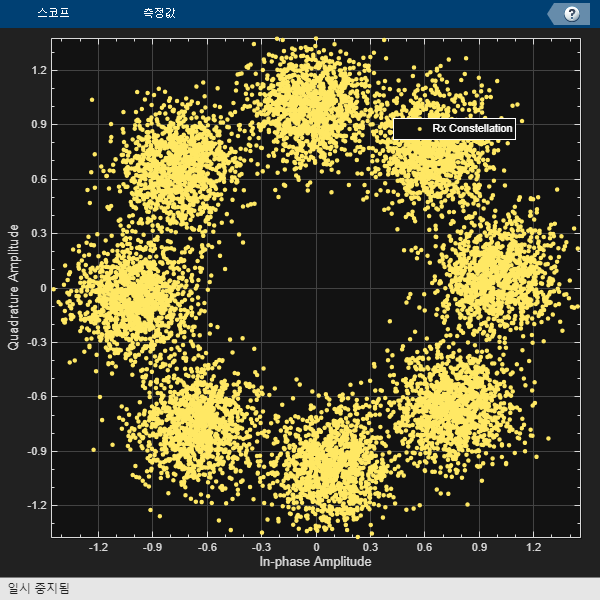

R = k/n;  % 코드율 계산 (number of input bits / number of channel uses)

% Eb/No 값을 코드율에 맞게 조정.
EbNoChannelVec = simParams.EbNoVec + 10*log10(R);

M = 2^k;  % 가능한 심볼의 수를 계산

% 송신 심볼의 성상도를 시각화할 객체 생성
txConst = comm.ConstellationDiagram(ShowReferenceConstellation=false, ...
  ShowLegend=true, ChannelNames={'Tx Constellation'});

% 수신 심볼의 성상도를 시각화할 객체 생성
rxConst = comm.ConstellationDiagram(ShowReferenceConstellation=false, ...
  ShowLegend=true, ChannelNames={'Rx Constellation'});

% BLER 값을 저장할 배열을 EbNoChannelVec 크기에 맞게 초기화    
BLER = zeros(size(EbNoChannelVec));

% 각 Eb/No 값에 대해 시뮬레이션을 수행
for trainingEbNoIdx = 1:length(EbNoChannelVec)
  EbNo = EbNoChannelVec(trainingEbNoIdx);  % 현재 Eb/No 설정

  % AWGN (Additive White Gaussian Noise) 채널을 설정합니다.
  chan = comm.AWGNChannel("BitsPerSymbol",2, ...
    "EbNo", EbNo, "SamplesPerSymbol", 1, "SignalPower", 1);

  numBlockErrors = 0;  % 블록 오류 수를 초기화합니다.
  frameCnt = 0;  % 전송한 프레임 수를 초기화합니다.

  % 프레임 전송을 반복합니다. 아마 최소 오류 수에 도달할 때까지 또는 최대 프레임 수에 도달할 때까지
  while (numBlockErrors < simParams.MinNumErrors) ...
      && (frameCnt < simParams.MaxNumFrames)

    % 무작위 정보 비트 생성
    d = randi([0 M-1],simParams.NumSymbolsPerFrame,1);

    % 정보 비트를 인코더에 입력하여 심볼을 생성합
    x = helperAEWEncode(d,txNet(1));

    % 송신 심볼의 성상도를 시각화
    txConst(x)

    % 채널을 통해 심볼을 전송
    y = chan(x);

    % 수신된 심볼의 성상도를 시각화
    rxConst(y)

    % 수신된 심볼을 디코더에 입력하여 원래 비트를 복원
    dHat = helperAEWDecode(y,rxNet(1));

    % 복원된 비트와 원래 비트를 비교하여 블록 오류 수를 증가
    numBlockErrors = numBlockErrors + sum(d ~= dHat);

    % 전송한 프레임 수를 증가
    frameCnt = frameCnt + 1;
  end

  % 현재 Eb/No 값에 대한 BLER을 계산
  BLER(trainingEbNoIdx) = numBlockErrors / (frameCnt * simParams.NumSymbolsPerFrame);
end

% 8PSK 심볼의 개수
M = 8;  
k = log2(M);  % log2(M)을 통해 k값 결정

% 오토인코더의 인코더 네트워크에서 심볼을 생성
symbols = (0:M-1)';
encodedSymbols = predict(txNet(1), eye(M));

% I/Q 성분 분리
I_encoded = real(encodedSymbols);
Q_encoded = imag(encodedSymbols);

% 각 심볼의 에너지 계산
energy_encoded = sum(abs(encodedSymbols).^2, 2);  % 각 좌표의 에너지


disp('오토인코더로 얻어진 심볼 좌표 (I/Q)와 에너지:');

오토인코더로 얻어진 심볼 좌표 (I/Q)와 에너지:


disp(table(I_encoded, Q_encoded, energy_encoded, 'VariableNames', {'I', 'Q', 'Energy'}));

              I                 Q       Energy
    ______________________    ______    ______

     -0.64234     -0.76642    0    0      1   
      0.99798     0.063457    0    0      1   
      -0.7498      0.66166    0    0      1   
     0.083664     -0.99649    0    0      1   
      0.64161      0.76703    0    0      1   
    -0.032484      0.99947    0    0      1   
     -0.99795    -0.064013    0    0      1   
      0.75805      -0.6522    0    0      1   




% 평균 에너지 계산
mean_energy_encoded = mean(energy_encoded);
disp(['오토인코더 성상도의 평균 에너지: ', num2str(mean_energy_encoded)]);

오토인코더 성상도의 평균 에너지: 1


Compare the results with that of an uncoded QPSK system with block length n=2. For this n value, the autoencoder gets the same BLER as an uncoded QPSK system.

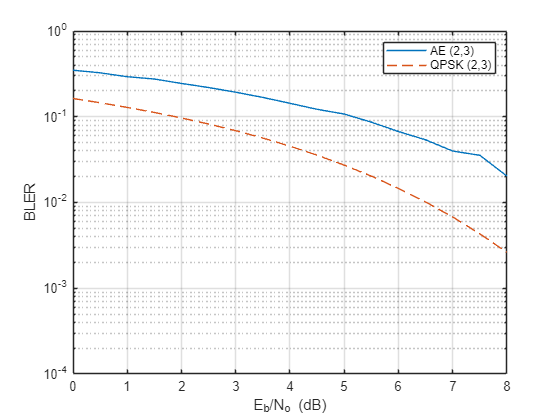

figure  


semilogy(simParams.EbNoVec, BLER, '-')  
hold on  % 다음 그래프를 동일한 그림에 겹쳐서 그리기 위해 hold on을 설정

% 비부호화된 QPSK 시스템의BLER 계산
% berawgn 함수는 AWGN 채널에서의 심볼 오류율을 계산하고, BLER 도출하는 함수일 것임

pskBLER = 1 - (1 - berawgn(EbNoChannelVec, 'psk', 2^k, 'nondiff')).^n;


semilogy(simParams.EbNoVec, pskBLER, '--')

hold off  

ylim([1e-4 1])


grid on


xlabel('E_b/N_o (dB)')


ylabel('BLER')


legend(sprintf('AE (%d,%d)', n, k), sprintf('QPSK (%d,%d)', n, k))

The well formed constellation together with the BLER results show that training for 10 epochs is enough to get a satisfactory convergence. 

## Compare Constellation Diagrams

Compare learned constellations of several autoencoders normalized to unit energy and unit average power. Train (2,4) autoencoder normalized to unit energy.

% (2,4) 오토인코더의 매개변수 설정
n = 2;      % 채널 사용 수 (number of channel uses)
k = 3;      % 입력 비트 수 (number of input bits)
EbNo = 9;   % 에너지 대 잡음 비율(Eb/No) (in dB)
normalization = "Energy";  % 정규화 방법을 "Energy"로 설정. 단위 에너지 정규화?

% 오토인코더 훈련 함수 호출
%  (n,k) 매개변수와 정규화 방법, 그리고 Eb/No 값으로 오토인코더를 훈련
[txNet(2),rxNet(2),infoTemp,wirelessAutoEncoder(2)] = ...
  helperAEWTrainWirelessAutoencoder(n,k,normalization,EbNo);

Output z:
    0.6657
    0.9481

Output z:
    1.3400
    1.1165

Output z:
    1.0669
    1.0491

Output z:
    0.8303   -0.6858   -0.0809   -0.7183    1.3646   -0.9329   -1.1228    0.6066   -0.1323    0.0749   -0.9448    0.7277   -0.2138   -0.8467    0.7924    1.2193   -0.4912    0.8770   -0.1451   -0.1252   -0.0207    0.2320   -0.8617   -0.0600    0.7152   -0.4159   -0.4675   -1.0771   -0.7155    1.1111   -0.1614    1.1400    0.7666    0.5722   -0.0970   -0.9869    1.0575    0.9860    0.0261    1.3634   -0.3968    1.1320    0.8869    0.8218    0.8580   -1.0127    0.9165    0.8922    0.8958   -0.2314    0.4289    0.6755    1.2562    1.0051    1.1060    0.6659    0.6518   -0.9627   -0.2483   -0.2412    0.9656   -0.1291    0.8953   -0.8508   -4.2512    0.9052   -1.0717   -0.0027    0.8617   -0.2790    1.4483    0.8901   -0.2289   -0.0928    1.0789    0.7589   -0.0747   -0.2612   -0.2329   -0.5302   -0.3502    0.9664   -0.2469    0.6125    1.6262    1.1748    0.9090   -0.2880   -0.1412 


% 훈련된 정보를 임시 변수에 저장
infoTemp.n = n;  % 채널 사용 수 저장
infoTemp.k = k;  % 입력 비트 수 저장
infoTemp.EbNo = EbNo;  % 훈련된 Eb/No 값 저장
infoTemp.Normalization = normalization;  % 정규화 방법 저장

% 훈련된 정보를 info 배열에 저장
info(2) = infoTemp;


Train (2,4) autoencoder normalized to unit average power.

n = 2;      % 채널 사용 수 (number of channel uses)
k = 3;      % 입력 비트 수 (number of input bits)
EbNo = 6;   % 에너지 대 잡음 비율(Eb/No) (in dB)
normalization = "Average power";  % 정규화 방법을 "Average power"로 설정. 평균 에너지 정규화?


% (n,k) 매개변수와 정규화 방법, 그리고 Eb/No 값으로 오토인코더 훈련
[txNet(3),rxNet(3),infoTemp,wirelessAutoEncoder(3)] = ...
  helperAEWTrainWirelessAutoencoder(n,k,normalization,EbNo);

Output z:
    0.6012
    0.8543

Output z:
    2.3226
    1.5315

Output z:
    0.9762
    0.7843

Output z:
   -0.2794   -0.8212   -0.2416   -0.7456   -0.7759   -1.2730   -0.1392   -0.5951   -0.2203   -0.8696   -0.7975    0.7487   -1.0699   -0.9187   -0.5186   -0.7494   -0.0810   -0.2667   -0.2843   -1.3989   -0.3964    0.2961   -1.5420    1.6737   -0.8808   -0.9576    0.2099   -0.8111   -0.5437   -0.8835   -0.6742    0.0406   -0.8458   -0.6038    0.5365   -1.0222   -0.9264   -1.1376    0.7939   -0.5615   -0.6596   -0.2941   -0.9139    0.0071   -0.5151   -0.7577   -0.4268    0.7139   -0.8693   -0.5935   -1.0271   -1.0453   -1.7113   -1.4277   -1.2934   -0.4461   -0.5300   -0.0195   -0.2828    0.1371   -0.7760    0.1488   -0.1897   -0.9493    0.3058   -0.8209   -0.4375    0.3080   -2.4270   -0.8245    0.0854   -0.9328   -2.6076    0.3440   -0.4138   -0.6910    0.1250    0.1423   -0.4362    0.6439   -0.3253   -0.7820   -1.1192   -0.5248   -0.6071   -0.4661   -1.1603   -0.6671   -0.7316 


% 훈련된 오토인코더의 정보를 임시 변수에 저장
infoTemp.n = n;  % 채널 사용 수 저장
infoTemp.k = k;  % 입력 비트 수 저장
infoTemp.EbNo = EbNo;  % 훈련된 Eb/No 값 저장
infoTemp.Normalization = normalization;  % 정규화 방법 저장

% 훈련된 오토인코더 정보를 info 배열에 저장
info(3) = infoTemp;


Train (7,4) autoencoder normalized to unit energy.

n = 7;      % 채널 사용 수 (number of channel uses)
k = 3;      % 입력 비트 수 (number of input bits)
EbNo = 3;   % 에너지 대 잡음 비율(Eb/No) (in dB)
normalization = "Energy";  % 정규화 방법을 "Energy"로 설정 (단위 에너지 정규화)


%  (n,k) 매개변수와 정규화 방법, 그리고 Eb/No 값으로 오토인코더 훈련
[txNet(4),rxNet(4),infoTemp,wirelessAutoEncoder(4)] = ...
  helperAEWTrainWirelessAutoencoder(n,k,normalization,EbNo);

% 훈련된 오토인코더의 정보를 임시 변수에 저장
infoTemp.n = n;  % 채널 사용 수 저장
infoTemp.k = k;  % 입력 비트 수 저장
infoTemp.EbNo = EbNo;  % 훈련된 Eb/No 값 저장
infoTemp.Normalization = normalization;  % 정규화 방법 저장

% 훈련된 정보를 info 배열에 저장
info(4) = infoTemp;


Plot the constellation using the [`helperAEWPlotConstellation.m`](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWPlotConstellation.m')) function. The trained (2,2) autoencoder converges on a QPSK constellation with a phase shift as the optimal constellation for the channel conditions experienced. The (2,4) autoencoder with energy normalization converges to a 16PSK constellation with a phase shift. Note that, energy normalization forces every symbol to have unit energy and places the symbols on the unit circle. Given this constraint, best constellation is a PSK constellation with equal angular distance between symbols. The (2,4) autoencoder with average power normalization converges to a three-tier constellation of 1-6-9 symbols. Average power normalization forces the symbols to have unity average power over time. This constraint results in an APSK constellation, which is different than the conventional QAM or APSK schemes. Note that, this network configuration may also converge to a two-tier constellation with 7-9 symbols based on the random initial condition used during training. The last plot shows the 2-D mapping of the 7-D constellation generated by the (7,4) autoencoder with energy constraint. 2-D mapping is obtained using the t-Distributed Stochastic Neighbor Embedding (t-SNE) method (see [tsne](docid:stats_ug#bvh3rti) function).  

figure  


subplot(2,2,1)
helperAEWPlotConstellation(txNet(1))  % 첫 번째 오토인코더의 성상도
title(sprintf('(%d,%d) %s', info(1).n, info(1).k, info(1).Normalization))  


subplot(2,2,2)
helperAEWPlotConstellation(txNet(2))  % 두 번째 오토인코더의 성상도.
title(sprintf('(%d,%d) %s', info(2).n, info(2).k, info(2).Normalization)) 


subplot(2,2,3)
helperAEWPlotConstellation(txNet(3))  % 세 번째 오토인코더의 성상도
title(sprintf('(%d,%d) %s', info(3).n, info(3).k, info(3).Normalization))  


subplot(2,2,4)
helperAEWPlotConstellation(txNet(4), 't-sne')  % 네 번째 오토인코더의 성상도
title(sprintf('(%d,%d) %s', info(4).n, info(4).k, info(4).Normalization))  

title(sprintf('(%d,%d) %s',info(4).n,info(4).k,info(4).Normalization))

## Compare BLER Performance of Autoencoders with Coded and Uncoded QPSK

Simulate the BLER performance of a (7,4) autoencoder with that of (7,4) Hamming code with QPSK modulation for both hard decision and maximum likelihood (ML) decoding. Use uncoded (4,4) QPSK as a baseline. (4,4) uncoded QPSK is basically a QPSK modulated system that sends blocks of 4 bits and measures BLER. The data for the following figures is obtained using [helperAEWSimulateBLER.mlx](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWSimulateBLER.mlx')) and [helperAEWPrepareAutoencoders.mlx](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWPrepareAutoencoders.mlx')) files. 

load codedBLERResults.mat
figure
qpsk44BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^4;
semilogy(simParams.EbNoVec,qpsk44BLERTh,':*')
hold on
semilogy(simParams.EbNoVec,qpsk44BLER,':o')
semilogy(simParams.EbNoVec,hammingHard74BLER,'--s')
semilogy(simParams.EbNoVec,ae74eBLER,'-')
semilogy(simParams.EbNoVec,hammingML74BLER,'--d')
hold off
ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend('Theoretical Uncoded QPSK (4,4)','Uncoded QPSK (4,4)','Hamming (7,4) Hard Decision', ...
  'Autoencoder (7,4)','Hamming (7,4) ML','Location','southwest')
title('BLER comparison of (7,4) Autoencoder')

As expected, hard decision (7,4) Hamming code with QPSK modulation provides about 0.6 dB $E_b/N_o$ advantage over uncoded QPSK, while the ML decoding of (7,4) Hamming code with QPSK modulation provides another 1.5 dB advantage for a BLER of $10^{-3}$. The (7,4) autoencoder BLER performance approaches the ML decoding of (7,4) Hamming code, when trained with 3 dB $E_b/N_o$. This BLER performance shows that the autoencoder is able to learn not only modulation but also channel coding to achieve a coding gain of about 2 dB for a coding rate of R=4/7. 

Next, simulate the BLER performance of autoencoders with R=1 with that of uncoded QPSK systems. Use uncoded (2,2) and (8,8) QPSK as baselines. Compare BLER performance of these systems with that of (2,2), (4,4) and (8,8) autoencoders. 

 %기존에 저장된 BLER 결과 데이터를 불러옴.
load uncodedBLERResults.mat
qpsk22BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^2;
semilogy(simParams.EbNoVec,qpsk22BLERTh,':*')
hold on
semilogy(simParams.EbNoVec,qpsk88BLER,'--*')
qpsk88BLERTh = 1-(1-berawgn(simParams.EbNoVec,'psk',4,'nondiff')).^8;
semilogy(simParams.EbNoVec,qpsk88BLERTh,':o')
semilogy(simParams.EbNoVec,ae22eBLER,'-o')
semilogy(simParams.EbNoVec,ae44eBLER,'-d')
semilogy(simParams.EbNoVec,ae88eBLER,'-s')
hold off
ylim([1e-5 1])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend('Uncoded QPSK (2,2)','Uncoded QPSK (8,8)','Theoretical Uncoded QPSK (8,8)', ...
  'Autoencoder (2,2)','Autoencoder (4,4)','Autoencoder (8,8)','Location','southwest')
title('BLER performance of R=1 Autoencoders')

Bit error rate of QPSK is the same for both (8,8) and (2,2) cases. However, the BLER depends on the block length, $n$, and gets worse as $n$ increases as given by $BLER = 1-(1-BER)^n$. As expected, BLER performance of (8,8) QPSK is worse than the (2,2) QPSK system. The BLER performance of (2,2) autoencoder matches the BLER performance of (2,2) QPSK. On the other hand, (4,4) and (8,8) autoencoders optimize the channel coder and the constellation jointly to obtain a coding gain with respect to the corresponding uncoded QPSK systems. 

## Effect of Training Eb/No on BLER Performance

Train the (7,4) autoencoder with energy normalization under different $E_b/N_o$ values and compare the BLER performance. To extend the BLER curve, set simParams.EbNoVec to -2:0.5:8.

n = 7;
k = 3;
normalization = 'Energy';
traningEbNoVec = -3:5:7;
simParams.EbNoVec = 0:4;
for trainingEbNoIdx = 1:length(traningEbNoVec)
  trainingEbNo = traningEbNoVec(trainingEbNoIdx);
  [txNetVec{trainingEbNoIdx},rxNetVec{trainingEbNoIdx},infoVec{trainingEbNoIdx},trainedNetVec{trainingEbNoIdx}] = ...
    helperAEWTrainWirelessAutoencoder(n,k,normalization,trainingEbNo); %#ok<SAGROW> 
  BLERVec{trainingEbNoIdx} = helperAEWAutoencoderBLER(txNetVec{trainingEbNoIdx},rxNetVec{trainingEbNoIdx},simParams); %#ok<SAGROW> 
end

Plot the BLER performance together with theoretical upper bound for hard decision decoded Hamming (7,4) code and simulated BLER of maximum likelihood decoded (MLD) Hamming (7,4) code. The BLER performance of the (7,4) autoencoder gets closer to the Hamming (7,4) code with MLD as the training $E_b/N_o$ decreases from 10 dB to 1 dB, at which point it almost matches the MLD Hamming (7,4) code. 

berHamming = bercoding(simParams.EbNoVec,'hamming','hard',n);
blerHamming = 1-(1-berHamming).^k;
hammingBLER = load('codedBLERResults');
figure
semilogy(simParams.EbNoVec,blerHamming,':k')
legendStr = sprintf('(%d,%d) Hamming HDD Upper',n,k);
hold on
linespec = {'-*','-d','-o','-s',};
for trainingEbNoIdx=length(traningEbNoVec):-1:1
  semilogy(simParams.EbNoVec,BLERVec{trainingEbNoIdx},linespec{trainingEbNoIdx})
  legendStr = [legendStr {sprintf('(%d,%d) AE - Training Eb/No=%1.1f', ...
    n,k,traningEbNoVec(trainingEbNoIdx))}]; %#ok<AGROW> 
end
semilogy(hammingBLER.simParams.EbNoVec,hammingBLER.hammingML74BLER,'--vk')
legendStr = [legendStr {'Hamming (7,4) MLD'}];
hold off
xlim([min(simParams.EbNoVec) max(simParams.EbNoVec)])
grid on
xlabel('E_b/N_o (dB)')
ylabel('BLER')
legend(legendStr{:},'location','southwest')

## Conclusions and Further Exploration

The BLER results show that it is possible for autoencoders to learn joint coding and modulation schemes in an unsupervised way. It is even possible to train an autoencoder with R=1 to obtain a coding gain as compared to traditional methods. The example also shows the effect of hyperparameters such as $E_b/N_o$ on the BLER performance. 

The results are obtained using the following default settings for training and BLER simulations:

trainParams.Plots = 'none';
trainParams.Verbose = false;
trainParams.MaxEpochs = 10;
trainParams.InitialLearnRate = 0.08;
trainParams.LearnRateSchedule = 'piecewise';
trainParams.LearnRateDropPeriod = 5;
trainParams.LearnRateDropFactor = 0.1;
trainParams.MiniBatchSize = 100*2^k;

simParams.EbNoVec = -2:0.5:8;
simParams.MinNumErrors = 100;
simParams.MaxNumFrames = 300;
simParams.NumSymbolsPerFrame = 10000;
simParams.SignalPower = 1;

Vary these parameters to train different autoencoders and test their BLER performance. Experiment with different n, k, normalization and $E_b/N_o$ values. See the help for [helperAEWTrainWirelessAutoencoder.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWTrainWirelessAutoencoder.m')), [helperAEWPrepareAutoencoders.mlx](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWPrepareAutoencoders.mlx')) and [helperAEWAutoencoderBLER.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWAutoencoderBLER.m')) for more information.

### List of Helper Functions

- [helperAEWAWGNLayer.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWAWGNLayer.m'))

- [helperAEWNormalizationLayer.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWNormalizationLayer.m'))

- [helperAEWEncode.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWEncode.m'))

- [helperAEWDecode.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWDecode.m'))

- [helperAEWTrainWirelessAutoencoder.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWTrainWirelessAutoencoder.m'))

- [helperAEWPlotConstellation.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWPlotConstellation.m'))

- [helperAEWPlotTrainingPerformance.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWPlotTrainingPerformance.m'))

- [helperAEWAutoencoderBLER.m](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWAutoencoderBLER.m'))

- [helperAEWPrepareAutoencoders.mlx](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWPrepareAutoencoders.mlx'))

- [helperAEWSimulateBLER.mlx](matlab:openExample('deeplearning_shared/AutoencodersForWirelessCommunicationsExample','supportingFile','helperAEWSimulateBLER.mlx'))

## References

[1] T. O’Shea and J. Hoydis, "An Introduction to Deep Learning for the Physical Layer," in IEEE Transactions on Cognitive Communications and Networking, vol. 3, no. 4, pp. 563-575, Dec. 2017, doi: 10.1109/TCCN.2017.2758370.

[2] S. Dörner, S. Cammerer, J. Hoydis and S. t. Brink, "Deep Learning Based Communication Over the Air," in *IEEE Journal of Selected Topics in Signal Processing*, vol. 12, no. 1, pp. 132-143, Feb. 2018, doi: 10.1109/JSTSP.2017.2784180.

*Copyright 2020-2022 The MathWorks, Inc.*